% script for digestates A and I

cd('path\B2') % raw data not uploaded, can be optained by contacting Johanna Pedersen 
p0 = imread('0.JPG'); 

light_org = imread('path\l1.JPG');

p0bw = (p0(:, :, 1) > 60);

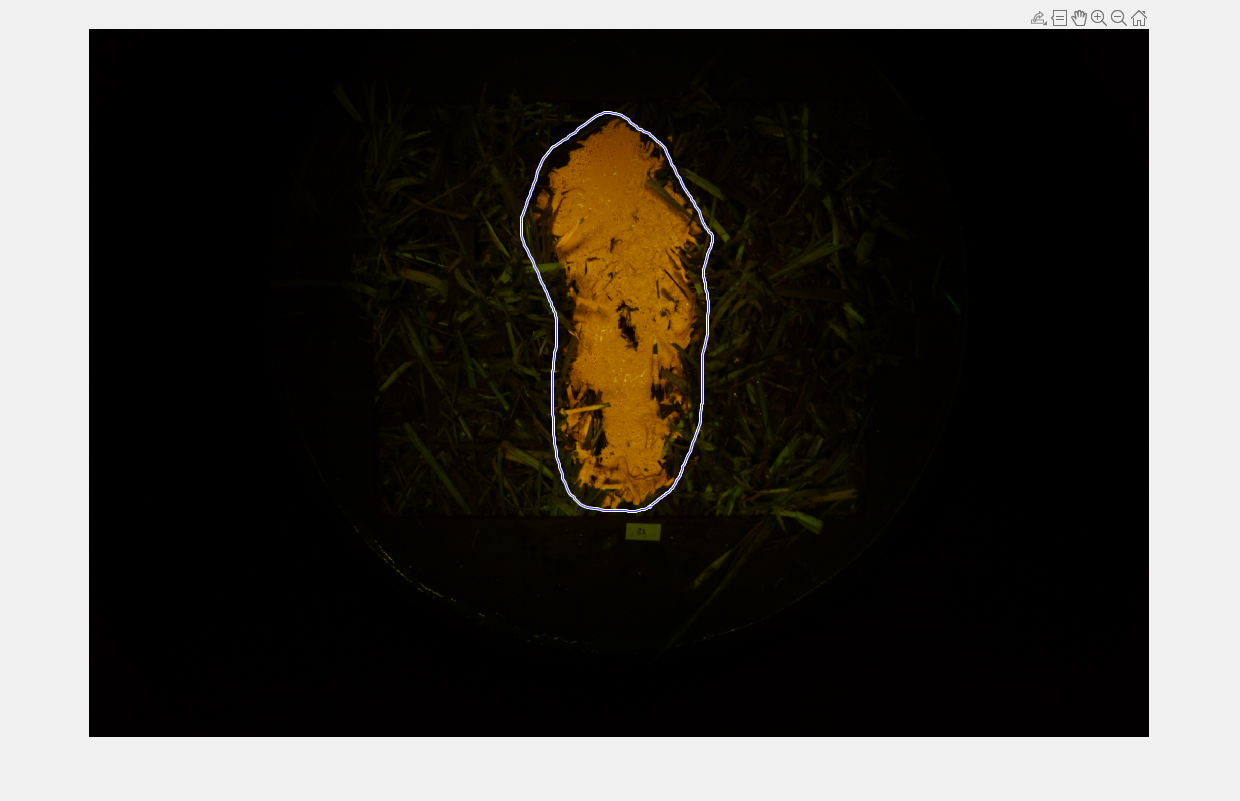

h =   imfreehand with properties:

    Deletable: 1


% need a mask due to the beaker with slurry
imshow(p0)
h = imfreehand

mask = createMask(h);
save mask

load('mask')

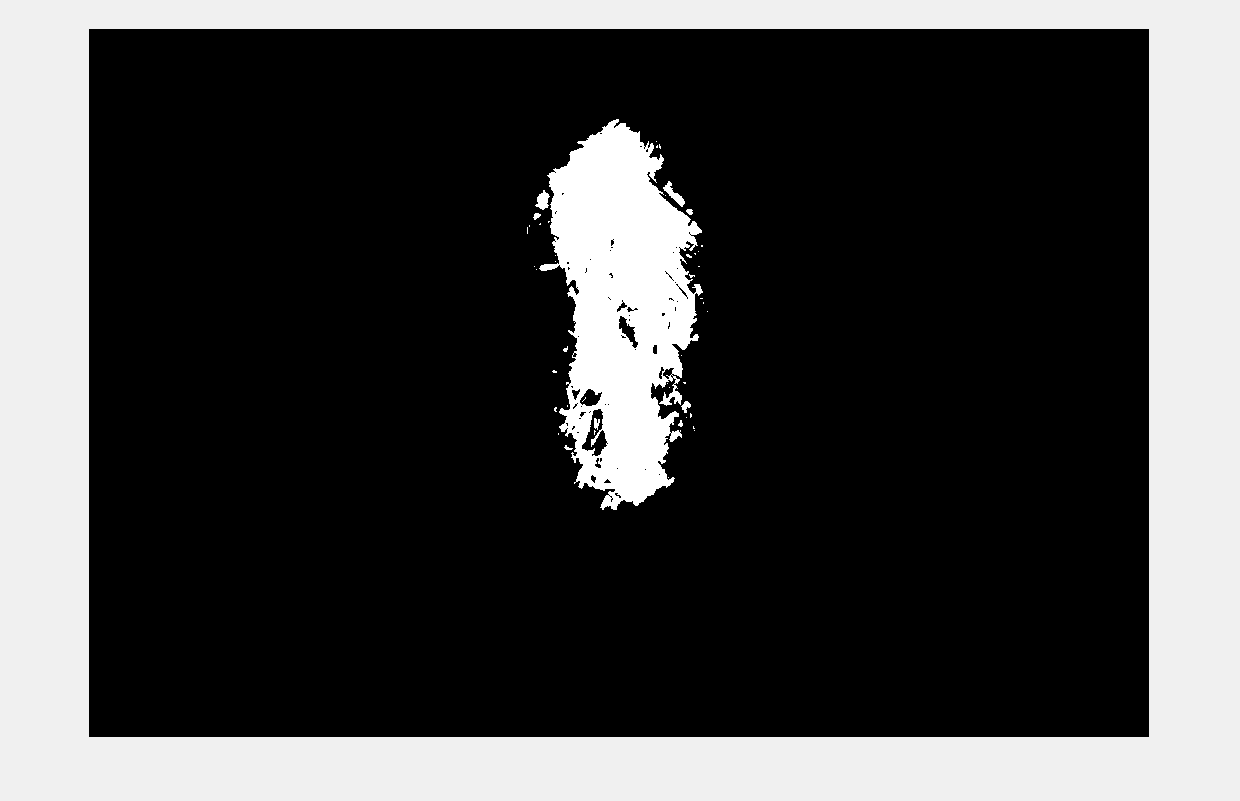

p0bw = p0bw.*mask; 

imshow(p0bw)


A0a = sum(p0bw(:));

test1_area = A0a .* slope

test1_area = 156.2741